clear;
if exist('DataSet','dir')
   rmdir('.\DataSet\', 's');
end

mkdir('.\DataSet\');

% 配置
global run_type;
run_type = 'io';
config;

%-----------------------------
% 产生信号
source;
tag;
global y_sig;
y_sig = y_source .* y_tag;

% dB 单位信噪比
y_noise = awgn(y_sig, 50);
y_sig = y_noise;

global Length;
global Width;

## 房间内的随机点

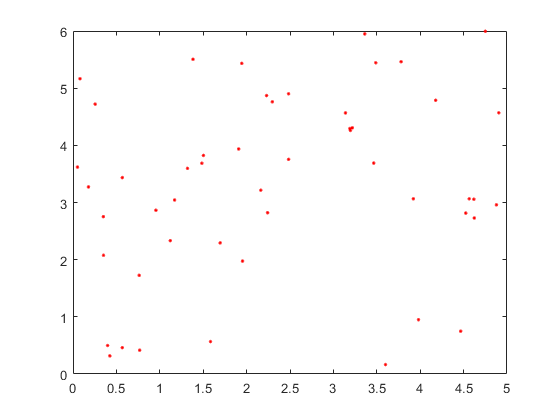

N_inside = 50;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);
figure; plot(x,y,'r.');


% 计算三个距离
[d1, d2, d3] = xy2d(x, y);

single_run(d1, d2, d3, false, 'inside');

  列 1 至 16

  107.7204  108.5952  111.1320  106.3443  109.0450  101.6369   98.0512  103.0048   98.9560   95.7254  100.0390  106.3567  103.3361  109.8990  103.5696  110.4540

  列 17 至 32

  100.3663  103.7793   99.8256  106.2426  108.5996  101.2041  100.2870  110.1592  109.3207   99.8043  109.9911  100.1719  103.5299  107.7718  107.0659  110.1300

  列 33 至 48

  101.3729   98.0412  104.2093  102.6303  106.4307  111.6243  110.7902  102.3063  100.1436  101.6841  101.0138   97.5290  104.2946  101.3398   98.4057  101.7543

  列 49 至 50

  102.4114  108.3030

delta t is
   1.0e-07 *

  列 1 至 16

    0.1380    0.1531    0.1976    0.1044    0.1565    0.0329    0.0304    0.0509    0.0385    0.0128    0.0134    0.1043    0.0685    0.1667    0.0697    0.1859

  列 17 至 32

    0.0113    0.0573    0.0468    0.1052    0.1552    0.0242    0.0125    0.1723    0.1612    0.0090    0.1687    0.0204    0.0540    0.1445    0.1129    0.1716

  列 33 至 48

    0.0272    0.0349    0.0798    0.0467    0.1059    

## 房间外的随机点

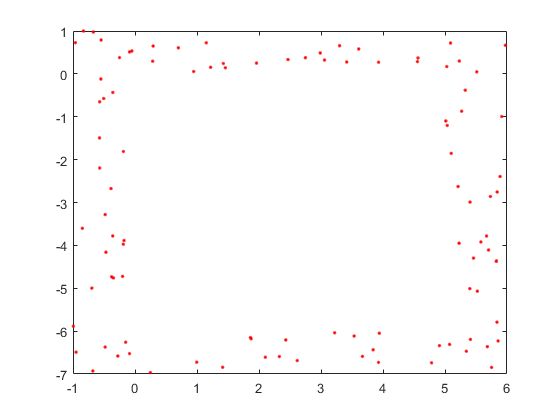

% 1/4 的数量
N_outside = 25;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
figure; plot(x0,y0,'r.');


% 计算三个距离
[d1_0, d2_0, d3_0] = xy2d2(x0, y0);
SinglePoint2(x0, y0, d1_0, d2_0, d3_0, false, 'outside');

  列 1 至 16

  156.2944  148.2333  119.2281  159.7235  135.0781  145.1083  157.0250  156.4135  152.5263  120.8673  150.1010  145.4564  120.3804  119.6062  121.8806  118.4309
  172.4588  160.2173  158.7061  178.4488  166.2143  162.3918  166.0402  162.6680  158.8207  159.1907  171.2874  164.9836  165.0825  200.3143  221.6171  218.8684
  119.9411  159.0570  152.0608  148.3221  161.2990  146.6842  160.7646  114.4417  116.6174  115.9088  157.6883  161.4484  119.2018  120.3159  119.3248  120.5031
  169.4450  140.2123  164.8790  171.7748  144.7103  151.1155  166.2264  164.0128  163.9902  169.0559  165.1309  174.5069  229.6225  169.3200  225.4711  176.2028

  列 17 至 25

  122.3260  119.6624  119.1625  121.6866  118.5306  118.8356  120.3249  117.9400  118.3209
  231.3296  229.3959  230.1028  221.3750  208.8860  191.9150  227.8452  159.5458  215.4326
  117.8420  119.0042  119.4671  119.7288  117.4708  117.6357  117.6535  117.5319  116.1676
  225.2198  226.9956  229.5804  222.4905  216.2711  231.1



% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end